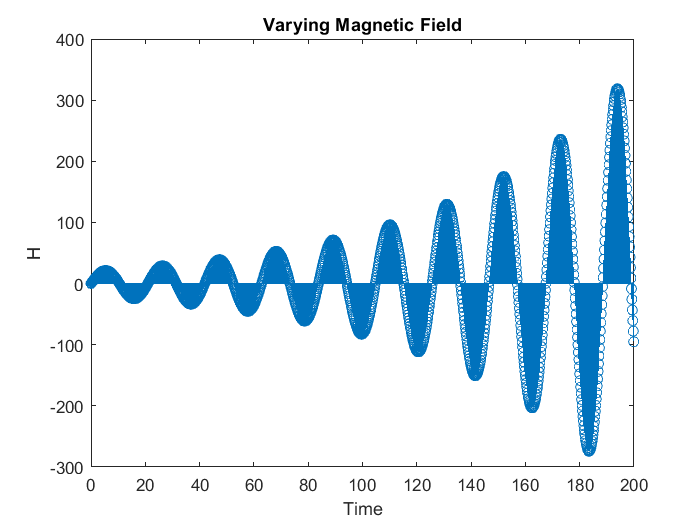

clear;

amp_sine = 20;            % Scaling amplitude of sine wave (default 20)
amp_exp = 70;             % Scaling amplitude of exponential factor (default 70)
amp_freq = 0.3;           % Scaling frequency of sine wave (default 0.3)

t = 0:0.1684:200;         % sampling rate (1188 samples)
Htest = amp_sine .* exp(t/amp_exp) .* sin(t * amp_freq);    % exponential sinusoidal form of H input
stem(t,Htest)
title('Varying Magnetic Field');
ylabel('H');
xlabel('Time');


H_coordinates = [t' Htest'];

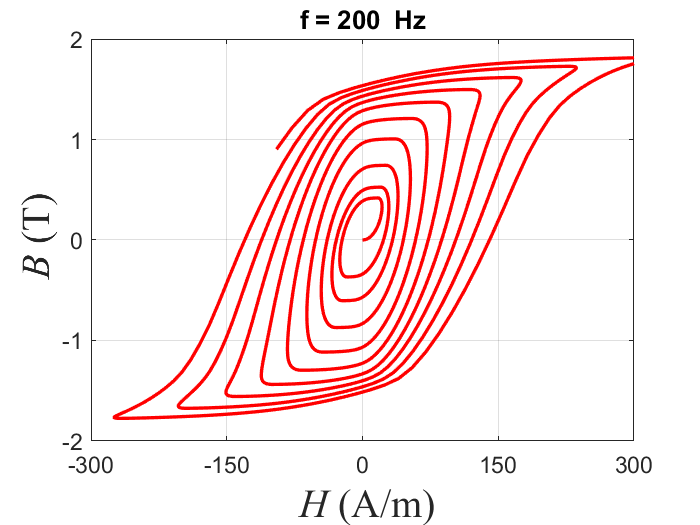

%Dinamikus Preisach modell, Lornent eloszlassal, derivalt analitikusan kozelitve

mu_0 = 4*pi*1e-7;

% --------------------------------------------------------------------
HB  = load('HB_frec_20TO500.txt');
par = load('param_mh.txt');

ind_frec = 5;

frec     = [20 50 100 150 200 300 400 500]; %Hz
ind_H    = [1 3 5 7 9 11 13 15];

n_i = par(1); %the number of Preisach functions
par = par(2:length(par));

%the parameters of the dynamic mnodel
am = 3056.5;
bm = 99.29;
cm = 0.69;

%for plotting
Hmin = -300;
Hmax = 300;
Bmin = -2;
Bmax = 2;

% --------------------------------------------------------------------
%convert the parameters
par_abc = par;
j = 1;
for i = 1:n_i
    par_abc(j+1) = 1.0/par(j+2);
    par_abc(j+2) = exp(par(j+1)*par_abc(j+1));
    par_abc(j)   = par(j)*par_abc(j+2);
    j = j+3;
end

Hsat = max(HB(:,ind_H(ind_frec)));  %the saturation - (limit of the Preisach triangle - technical saturation for convenience)

n_periods = 12;
n_HB   = size(HB);
n_HB_1 = n_HB(1) - 1;
n_H    = n_HB(1)*n_periods - n_periods;
H      = zeros(n_H,1);

T  = 1/frec(ind_frec);
dt = T/n_HB(1);

for i = 1:n_periods
    H((i-1)*n_HB_1+1:i*n_HB_1) = HB(2:n_HB(1),ind_H(ind_frec));
end

% n_ramp_per = n_periods - 2;
% ramp = linspace(0,1,n_ramp_per*n_HB(1));
% ramp = [ramp ones(1,(n_periods - n_ramp_per)*n_HB(1) - n_periods)];

H = Htest;

n_m  = 2;
nLa  = 1;
Lj   = zeros(n_m,2); %a lepcsosgorbe inicializalasa
Lj_r = Lj;

B      = zeros(1,n_H);
M      = zeros(1,n_H);
Hm     = zeros(1,n_H);
dMpdHm = zeros(1,n_H);
H_r    = 0;
Hm_r   = 0;
dMpdHm(1) = kimenet_dMpdH_AnEv_abc(par_abc,n_i,Lj);
dMpdHm_r  = dMpdHm(1);

amORdtDIV2   = am*dt*0.5;
mu_0ORbm     = mu_0*bm;
mu_0ORbmDIV2 = mu_0*bm*0.5;
for i = 1:n_H
    hiba = 1;

    while (hiba > 1e-6)
        %the modified magnetic field intensity, which is the input of the
        %hysteresis model
        num_1 = 1 + mu_0ORbmDIV2*(dMpdHm(i) + dMpdHm_r);
        Hm(i) = ( (num_1 - amORdtDIV2)*Hm_r + (amORdtDIV2 + cm - mu_0ORbm)*H(i) + (amORdtDIV2 - cm + mu_0ORbm)*H_r )/(num_1 + amORdtDIV2);

        %set the starcaise line for Hm
        [Lj,nLa] = vectf_all_1(Lj_r,Hm(i));

        %the derivative in function of Hm
        dMpdHm_1 = kimenet_dMpdH_AnEv_abc(par_abc,n_i,Lj);

        %calculate the difference
        delta     = dMpdHm_1 - dMpdHm(i);
        %update dMpdHm
        dMpdHm(i) = dMpdHm(i) + 0.5*delta;

        %error
        if delta > 0
            hiba = delta;
        else
            hiba = -delta;
        end

        %str = sprintf('i = %d, hiba = %g, diff = %g',i,hiba,dMpdHm_1 - dMpdHm(i));
        %disp(str);
    end
    dMpdHm(i) = dMpdHm_1;%kimenet_dMpdH_AnEv(par,n_i,Lj);
    dMpdHm_r  = dMpdHm(i);

    %calculate the magnetization corresponding to Hm
    M(i)     = kimenet_ClForm_abc(par_abc,n_i,Lj);
    B(i)     = mu_0*(Hm(i) + M(i));

    Hm_r = Hm(i);
    H_r  = H(i);
    Lj_r = Lj;

    %str = sprintf('i = %d',i);
    %disp(str);
end

% Create CSV files from output (H, B, HB):
% writematrix(H, 'H.csv');
% for k1 = 1:length(H)
%     fprintf('Number at position in H %d = %6.2f\n', k1, H(k1));
% end
% B = reshape(B, length(B), 1);
% writematrix(B, 'B.csv');
% for k2 = 1:length(B)
%     fprintf('Number at position in B %d = %6.2f\n', k2, B(k2));
% end
% writematrix([H,B], 'HB.csv');

%plot the hysteresis loop
figure
set(gcf,'Color',[1,1,1]);
h3 = plot(H,B,'Color','r','LineWidth',2);
hold on;
grid on;
box on;
set(gca,'FontSize',14);
axis([Hmin Hmax Bmin Bmax]);
set(gca,'XTick',linspace(Hmin,Hmax,5));
set(gca,'YTick',linspace(Bmin,Bmax,5));
xlabel('\it H \rm(A/m)','fontname','Times New Roman','fontsize',24);
ylabel('\it B \rm(T)','fontname','Times New Roman','fontsize',24);
title(['f = ', int2str(frec(ind_frec)), '  Hz' ]);


% CSV Formatting
H = H';
B = B';
t = t';

function dMpdH = kimenet_dMpdH_AnEv_abc(par,n,Lj)

nLj = size(Lj);
H   = Lj(nLj(1),1);

dMpdH = 0;
if nLj(1) > 1
    j = 1;
    for i = 1:n
        a = par(j);
        b = par(j+1);
        c = par(j+2);

        if abs( Lj(nLj(1),2) - Lj(nLj(1)-1,2) )<1e-9 %a Lepcsosgorbe utolso szakasza vizszintes, felfele haladok
            H_r = Lj(nLj(1)-1,1);

            par_1 = exp(-b*H);

            dMpdH = dMpdH + 2*a^2/(b*c)*par_1/(1 + c*par_1)^2*( 1/(1 + c*exp(b*H_r)) - 1/(1 + c*exp(b*H)) );
        else    % a lepcsosgorbe utolso szakasza fuggoleges, lefele haladok
            H_r = Lj(nLj(1)-1,2);

            par_1 = exp(b*H);

            dMpdH = dMpdH + 2*a^2/(b*c)*par_1/(1 + c*par_1)^2*( 1/(1 + c*exp(-b*H_r)) - 1/(1 + c*exp(-b*H)));
        end

        j = j + 3;
    end
end

n_d     = length(par);
n_x_rev = (n_d - 1 - 3*n)/2;
dMpdH_rev   = abs(par(n_d)); % (d*H)' = d
j = 3*n + 1;
for i = 1:n_x_rev
    OneDIVK2  = 1/abs(par(j+1));
    dMpdH_rev = dMpdH_rev + abs(par(j))*OneDIVK2*( 1 - tanh(H*OneDIVK2).^2 );
    j = j + 2;
end
dMpdH = dMpdH + dMpdH_rev;
end
function [L, nL1] = vectf_all_1(Lj, H)

eps = 1e-8;

nLj = size(Lj);
H_r = Lj(nLj(1),1);

if abs(H) < 1e-16   && abs(H_r) < 1e-16
    L   = [ 0 0];
    nL1 = 1;
    return;
end

if (H >= H_r) %&& abs(H - H_r) > eps
    if Lj(1,1) ~= -1 && Lj(1,2) ~= 1
        if H > Lj(1,2) || abs(H - Lj(1,2)) < eps
            Lj = [-H H
                H H];
        else
            for i = nLj(1):-1:1
                if (H <= Lj(i,2)) && (H >= Lj(i+1,2))
                    break;
                end
            end
            Lj1 = Lj;
            Lj  = [Lj1(1:i,:)
                Lj1(i,1) H
                H H];
        end
    else
        for i = nLj(1):-1:1
            if (H <= Lj(i,2)) && (H >= Lj(i+1,2))
                break;
            end
        end
        Lj1 = Lj;
        Lj  = [Lj1(1:i,:)
            Lj1(i,1) H
            H H];
    end
elseif (H < H_r) %&& abs(H - H_r) > eps
    if Lj(1,1) ~= -1 && Lj(1,2) ~= 1
        if H < Lj(1,1) || abs(H - Lj(1,1)) < eps
            Lj = [H -H
                H  H];
        else
            for i = nLj(1):-1:1
                if (H >= Lj(i,1)) && (H <= Lj(i+1,1))
                    break;
                end
            end
            Lj1 = Lj;
            Lj  = [Lj1(1:i,:)
                H Lj1(i,2)
                H H];
        end
    else
        for i = nLj(1):-1:1
            if (H >= Lj(i,1)) && (H <= Lj(i+1,1))
                break;
            end
        end
        Lj1 = Lj;
        Lj  = [Lj1(1:i,:)
            H Lj1(i,2)
            H H];
    end
end


nLj = size(Lj);
jel = 1;
for i = 1:nLj(1)-1
    if Lj(i,1) == Lj(i+1,1) && Lj(i,2) == Lj(i+1,2)
        jel = 0;
        break;
    end;
end;

if jel == 0
    L = [Lj(1:i-1,1) Lj(1:i-1,2)
        Lj(i+2:nLj,1) Lj(i+2:nLj,2)];
else
    L = Lj;
end;

nL1  = size(L);
end
function M = kimenet_ClForm_abc(par,n,Lj)

n_Lj = size(Lj);
M    = 0;
if n_Lj(1)>1

    %ind_Lj = 1:n_Lj(1)-1;
    %x = Lj(ind_Lj,1);
    %y = Lj(ind_Lj,2);

    %this seems to be faster, but one point of Ev (h1 == h2) is computed in excess
    x = Lj(:,1);
    y = Lj(:,2);

    Ev = 0;
    j = 1;
    for i = 1:n
        a = par(j);
        b = par(j+1);
        c = par(j+2);

        par_1 = exp(b*x);
        par_2 = exp(b*y);

        if c == 1
            Ev = Ev + 0.5*(a/b)^2*( (par_1 - par_2).^2 )./( ((1.0 + par_1).^2) .* ((1.0 + par_2).^2) );
        else
            cORcMin1 = c*c - 1.0;
            par_3 = (1.0 + c*par_1).*(c + par_2);

            Ev = Ev - (a/b)^2*( cORcMin1*(par_1 - par_2) + par_3.*log( (1.0 + c*par_2).*(c + par_1)./par_3) )./...
                (cORcMin1^2*par_3);
        end
        j = j + 3;
    end

    if Lj(1,1) == Lj(2,1)
        M = -Ev(1);
    else
        M = Ev(1);
    end

    for i = 2:n_Lj(1)-1
        if Lj(i,1) == Lj(i+1,1)
            %M = M - 2*Ev(i);
            M = M - (Ev(i) + Ev(i)); %seems to be faster
        elseif Lj(i,2) == Lj(i+1,2)
            %M = M + 2*Ev(i);
            M = M + (Ev(i) + Ev(i)); %seems to be faster
        end
    end
end

n_d     = length(par);
n_x_rev = (n_d - 1 - 3*n)/2;
M_rev   = abs(par(n_d))*Lj(n_Lj(1),1); %d*H
j = 3*n + 1;
for i = 1:n_x_rev
    M_rev = M_rev + abs(par(j))*tanh(Lj(n_Lj(1),1)/abs(par(j+1)));
    j = j + 2;
end
M = M + M_rev;
end